
clear all, close all, clc

m = 1;
M = 5;
l = 2;
g = -10;


A = [0 1 0 0;
    (M+m)*g/(M*l) 0 0 0;
    0 0 0 1;
    -m*g/M 0 0 0];
B = [0; 1/(M*l); 0; 1/M];

Q = [1 0 0 0;
    0 1 0 0;
    0 0 10 0;
    0 0 0 100];
R = .0001;

%%
det(ctrb(A,B))

ans = 0.0196

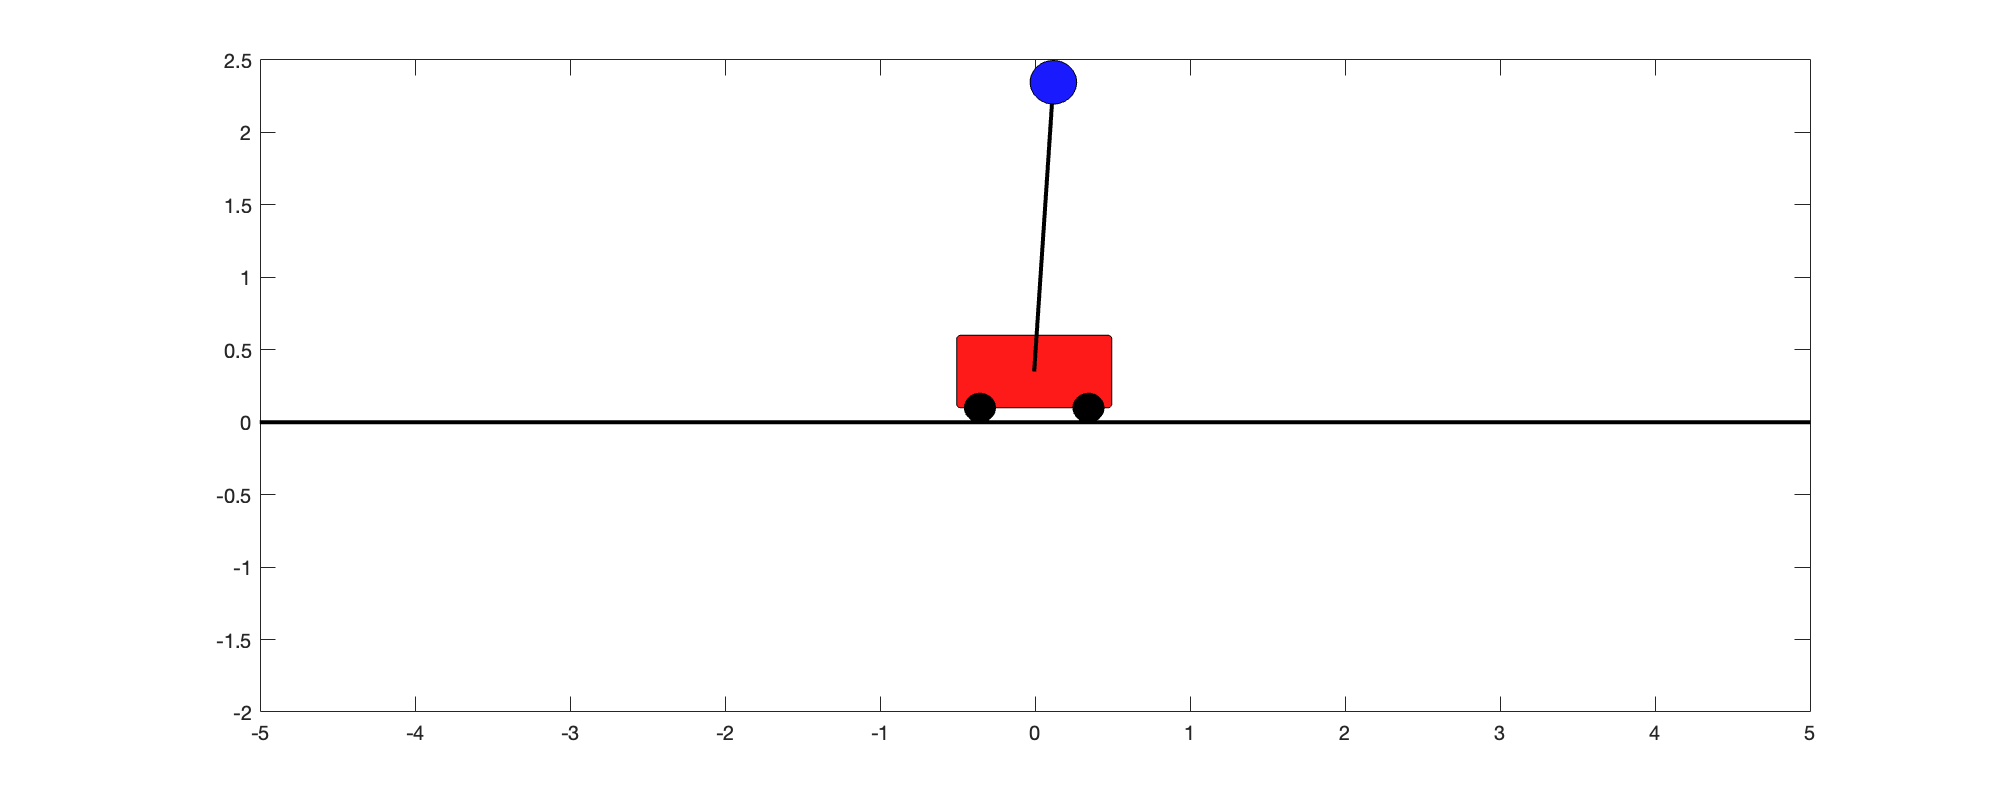


%%
K = lqr(A,B,Q,R);

tspan = 0:.001:10;
y0 = [pi+0.1; 0; 0; 0];
[t,y] = ode45(@(t,y)((A-B*K)*(y-[pi; 0; 0; 0])),tspan,y0);

figure();
for k=1:100:length(tspan)
    drawcartpend(y(k,:),m,M,l);
end

%Linear Euqaiton for cart on a pendulum

function dy = cartpend(y,m,M,l,g,u)

dy(1,1) = y(2);
dy(2,1) = (M+m)*g*y(1)/(M*l) + u/(M*l);
dy(3,1) = y(4);
dy(4,1) = -m*g*y(1)/M  + u/M;
end

function drawcartpend(y,m,M,l)
x = y(3);
th = y(1);

% kinematics
% x = 3;        % cart position
% th = 3*pi/2;   % pendulum angle

% dimensions
% L = 2;  % pendulum length
W = 1*sqrt(M/5);  % cart width
H = .5*sqrt(M/5); % cart height
wr = .2; % wheel radius
mr = .3*sqrt(m); % mass radius

% positions
% y = wr/2; % cart vertical position
y = wr/2+H/2; % cart vertical position
w1x = x-.9*W/2;
w1y = 0;
w2x = x+.9*W/2-wr;
w2y = 0;

px = x + l*sin(th);
py = y - l*cos(th);

plot([-10 10],[0 0],'k','LineWidth',2)
hold on
rectangle('Position',[x-W/2,y-H/2,W,H],'Curvature',.1,'FaceColor',[1 0.1 0.1])
rectangle('Position',[w1x,w1y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])
rectangle('Position',[w2x,w2y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])

plot([x px],[y py],'k','LineWidth',2)

rectangle('Position',[px-mr/2,py-mr/2,mr,mr],'Curvature',1,'FaceColor',[.1 0.1 1])

% set(gca,'YTick',[])
% set(gca,'XTick',[])
xlim([-5 5]);
ylim([-2 2.5]);
set(gcf,'Position',[100 550 1000 400])
% box off

%Draw Now- Draws flipbook
drawnow
%
%pause(0.2)

hold off
end